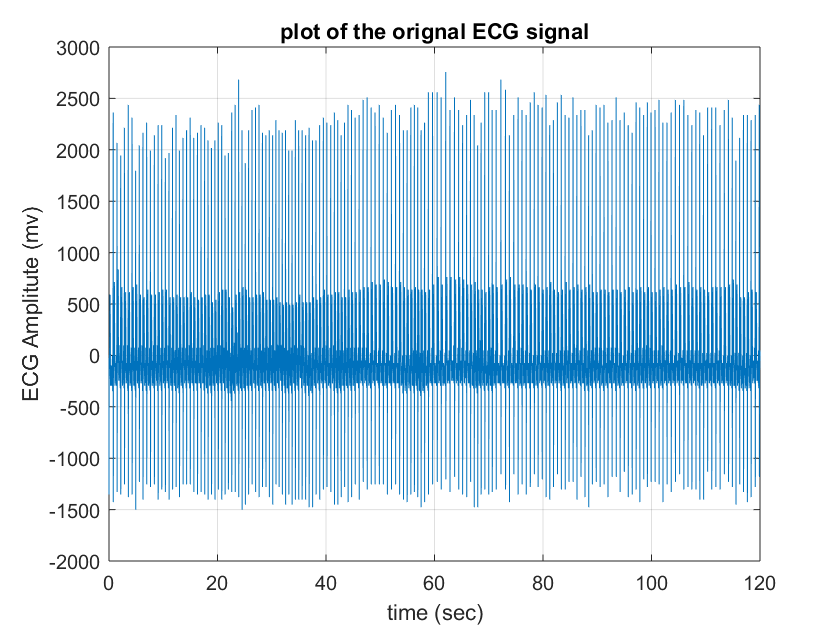

%close all;
%clear all;
%clc;
%
%S=load('I:\BIOM_Signal_processing\Hw5\ECGsignal_1.mat')
y1= dat;%DREAMER.Data{1,1}.ECG.stimuli{1,1}; %xlsread('J:\BIOM_Signal_processing\Hw5\ECGsignal_1.xls');
fs = 300; % find the sampling rate or frequency
T = 1/fs;% sampling rate or frequency
% find the length of the data per second
N = length(y1);
ls = size(y1);
t = (0 : N-1)/fs;% sampling period

figure; %subplot(1,2,1);
%subplot(1,2,1);
plot(t,y1);
title ('plot of the orignal ECG signal');
xlabel ('time (sec)');
ylabel ('ECG Amplitute (mv)');
grid on;

figure;

## Create a period

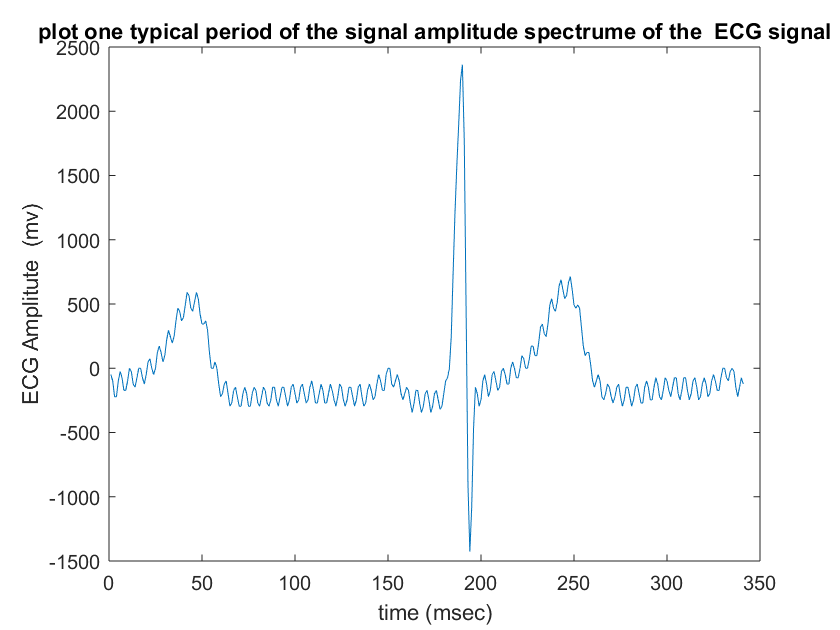

y1new = y1(10:350);
ax = axis; axis([ax(1:2) -3.2 3.2])
t2 = (0 : length (y1new)-1)/fs;% sampling period
%subplot(1,2,2);
plot (y1new);
title ('plot one typical period of the signal amplitude spectrume of the  ECG signal');
xlabel ('time (msec)');
ylabel ('ECG Amplitute  (mv)');



figure;

## Create a period

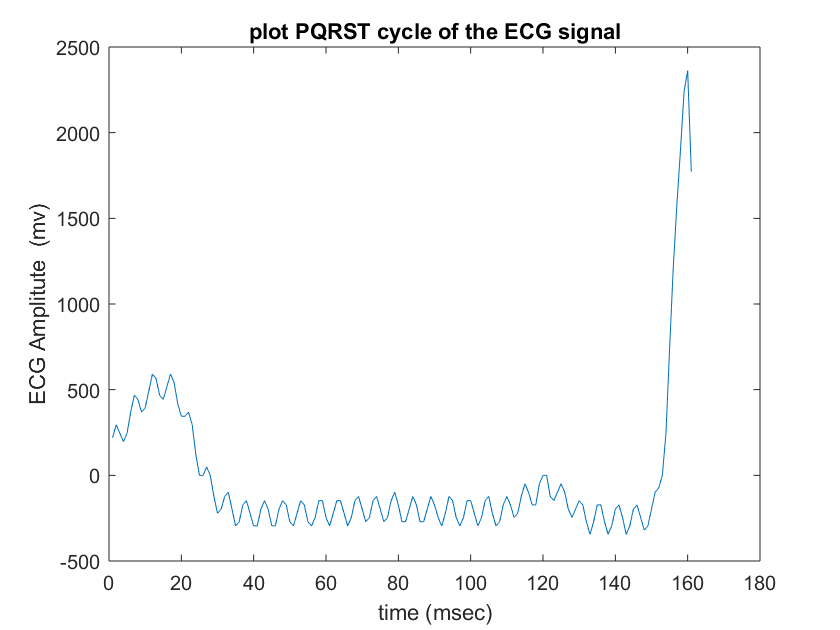

y1new1 = y1(40:200);
ax = axis; axis([ax(1:2) -3.2 3.2])
t2 = (0 : length (y1new)-1)/fs;% sampling period
%subplot(1,2,2);
plot (y1new1);
title ('plot PQRST cycle of the ECG signal');
xlabel ('time (msec)');
ylabel ('ECG Amplitute  (mv)');

## heart rate analysis

count the dominat peak

beat_count =0;
for k = 2 : length(y1)-1
    %the peak has to be greater than 1 and greater than the value before it and greater then the value after it.
    if(y1(k)> y1(k-1) && y1(k) > y1(k+1) && y1(k)> 1)
         beat_count = beat_count +1;
    end       
end
display (k);

k = 30719

disp('dominant peaks');

dominant peaks


## divide the peak count by the duration in minute

duration_in_sec = N/fs;
duration_in_minute = duration_in_sec/60;
BPM = beat_count/duration_in_minute;